clc;
clear all;
close all;
%..............................................................
% Initiation
%..............................................................
no_of_data_bits = 64%Number of bits per channel extended to 128

no_of_data_bits = 64

M =4%Number of subcarrier channel

M = 4

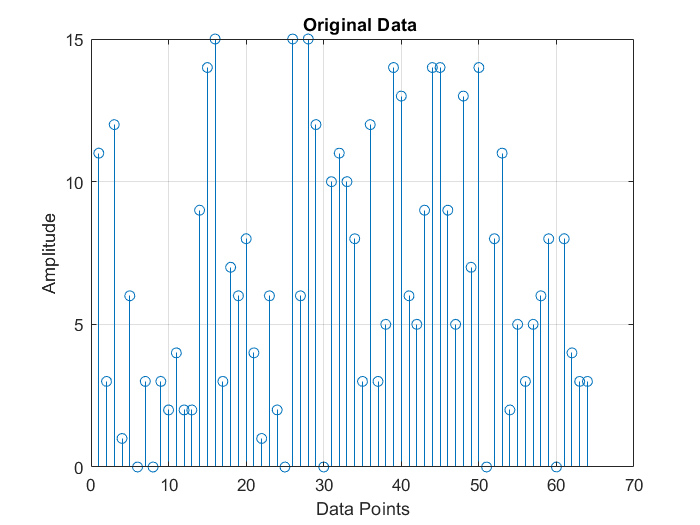

n=256;%Total number of bits to be transmitted at the transmitter
block_size = 16; %Size of each OFDM block to add cyclic prefix
cp_len = floor(0.1 * block_size); %Length of the cyclic prefix
%............................................................
% Transmitter
%.........................................................
%.........................................................
% Source generation and modulation
%........................................................
% Generate random data source to be transmitted of length 64
data = randsrc(1, no_of_data_bits, 0:block_size-1);
figure(1),stem(data); grid on; xlabel('Data Points'); ylabel('Amplitude')
title('Original Data ')

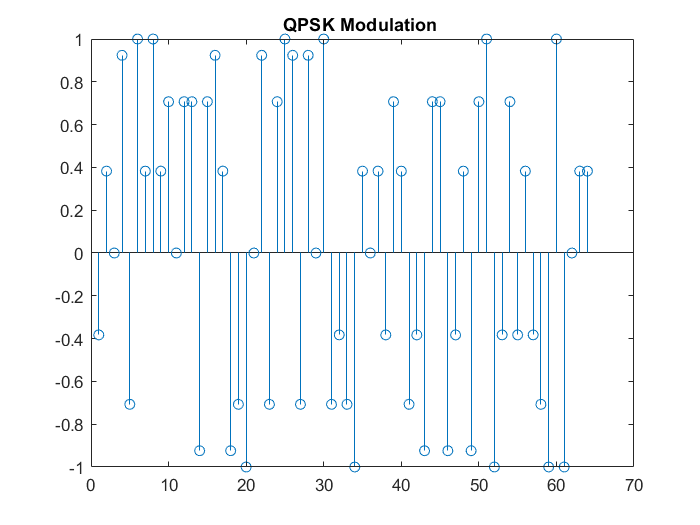

% Perform QPSK modulation on the input source data
qpsk_modulated_data = pskmod(data, block_size);
figure(2),stem(qpsk_modulated_data);title('QPSK Modulation ')

%............................................................
%.............................................................
% Converting the series data stream into four parallel data stream to form
% four sub carriers
S2P = reshape(qpsk_modulated_data, no_of_data_bits/M,M)

S2P =   -0.3827 - 0.9239i   0.3827 + 0.9239i  -0.7071 - 0.7071i  -0.9239 + 0.3827i
   0.3827 + 0.9239i  -0.9239 + 0.3827i  -1.0000 + 0.0000i   0.7071 - 0.7071i
  -0.0000 - 1.0000i  -0.7071 + 0.7071i   0.3827 + 0.9239i   1.0000 + 0.0000i
   0.9239 + 0.3827i  -1.0000 + 0.0000i  -0.0000 - 1.0000i  -1.0000 + 0.0000i
  -0.7071 + 0.7071i   0.0000 + 1.0000i   0.3827 + 0.9239i  -0.3827 - 0.9239i
   1.0000 + 0.0000i   0.9239 + 0.3827i  -0.3827 + 0.9239i   0.7071 + 0.7071i
   0.3827 + 0.9239i  -0.7071 + 0.7071i   0.7071 - 0.7071i  -0.3827 + 0.9239i
   1.0000 + 0.0000i   0.7071 + 0.7071i   0.3827 - 0.9239i   0.3827 + 0.9239i
   0.3827 + 0.9239i   1.0000 + 0.0000i  -0.7071 + 0.7071i  -0.3827 + 0.9239i
   0.7071 + 0.7071i   0.9239 - 0.3827i  -0.3827 + 0.9239i  -0.7071 + 0.7071i


Sub_carrier1 = S2P(:,1)

Sub_carrier1 =   -0.3827 - 0.9239i
   0.3827 + 0.9239i
  -0.0000 - 1.0000i
   0.9239 + 0.3827i
  -0.7071 + 0.7071i
   1.0000 + 0.0000i
   0.3827 + 0.9239i
   1.0000 + 0.0000i
   0.3827 + 0.9239i
   0.7071 + 0.7071i


Sub_carrier2 = S2P(:,2)

Sub_carrier2 =    0.3827 + 0.9239i
  -0.9239 + 0.3827i
  -0.7071 + 0.7071i
  -1.0000 + 0.0000i
   0.0000 + 1.0000i
   0.9239 + 0.3827i
  -0.7071 + 0.7071i
   0.7071 + 0.7071i
   1.0000 + 0.0000i
   0.9239 - 0.3827i


Sub_carrier3 = S2P(:,3)

Sub_carrier3 =   -0.7071 - 0.7071i
  -1.0000 + 0.0000i
   0.3827 + 0.9239i
  -0.0000 - 1.0000i
   0.3827 + 0.9239i
  -0.3827 + 0.9239i
   0.7071 - 0.7071i
   0.3827 - 0.9239i
  -0.7071 + 0.7071i
  -0.3827 + 0.9239i


Sub_carrier4 = S2P(:,4)

Sub_carrier4 =   -0.9239 + 0.3827i
   0.7071 - 0.7071i
   1.0000 + 0.0000i
  -1.0000 + 0.0000i
  -0.3827 - 0.9239i
   0.7071 + 0.7071i
  -0.3827 + 0.9239i
   0.3827 + 0.9239i
  -0.3827 + 0.9239i
  -0.7071 + 0.7071i


figure(3), subplot(4,1,1),stem(Sub_carrier1),title('Subcarrier1'),grid on;

subplot(4,1,2),stem(Sub_carrier2),title('Subcarrier2'),grid on;

subplot(4,1,3),stem(Sub_carrier3),title('Subcarrier3'),grid on;

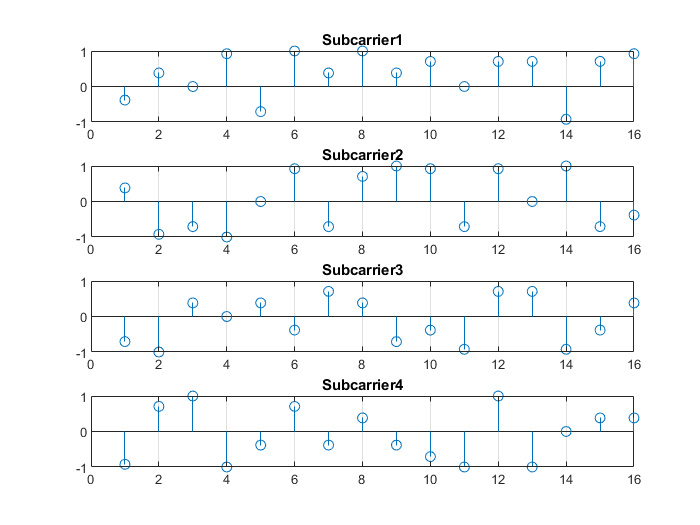

subplot(4,1,4),stem(Sub_carrier4),title('Subcarrier4'),grid on;

%..................................................................
%..................................................................
% IFFT OF FOUR SUB_CARRIERS
%.................................................................
%..............................................................
number_of_subcarriers=4;
cp_start=block_size-cp_len;
ifft_Subcarrier1 = ifft(Sub_carrier1)

ifft_Subcarrier1 =    0.3632 + 0.2241i
  -0.0988 - 0.2875i
  -0.0828 - 0.1007i
   0.0099 + 0.0904i
  -0.1019 - 0.0745i
  -0.2007 - 0.1315i
  -0.2254 - 0.0123i
  -0.0035 - 0.0291i
  -0.2269 - 0.0203i
   0.0645 - 0.4699i


ifft_Subcarrier2 = ifft(Sub_carrier2)

ifft_Subcarrier2 =    0.0454 + 0.1326i
  -0.5414 - 0.1884i
  -0.0450 - 0.0546i
  -0.0597 + 0.1036i
   0.2018 + 0.0741i
  -0.2576 + 0.1450i
   0.2664 - 0.0354i
   0.2612 - 0.0884i
  -0.2261 + 0.1597i
   0.0892 + 0.1788i


ifft_Subcarrier3 = ifft(Sub_carrier3)

ifft_Subcarrier3 =   -0.1099 - 0.0697i
  -0.1800 + 0.0111i
  -0.2007 - 0.0629i
   0.2416 - 0.0534i
  -0.3205 - 0.2939i
  -0.1056 - 0.4463i
  -0.1586 + 0.0239i
   0.1262 + 0.0231i
   0.0422 + 0.1915i
   0.0239 + 0.2430i


ifft_Subcarrier4 = ifft(Sub_carrier4)

ifft_Subcarrier4 =   -0.0760 + 0.3616i
   0.2138 - 0.0562i
   0.2799 + 0.0805i
   0.0510 + 0.0440i
  -0.1593 - 0.0952i
  -0.2138 + 0.1135i
   0.0438 + 0.0681i
   0.0645 - 0.0931i
  -0.2601 - 0.0828i
   0.0785 + 0.1748i


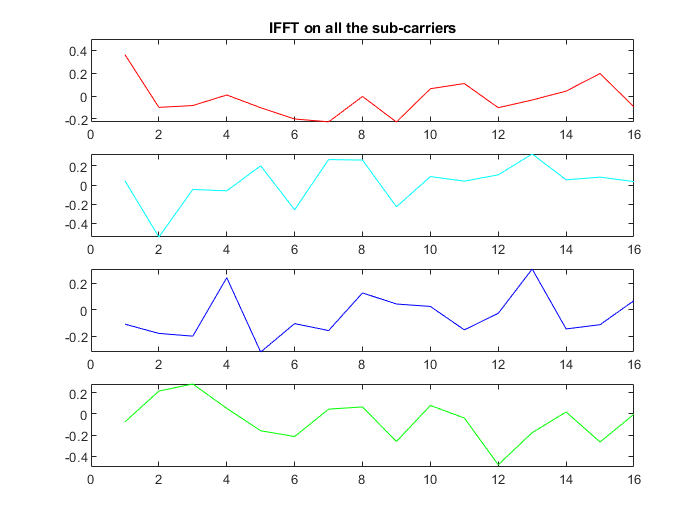

figure(4), subplot(4,1,1),plot(real(ifft_Subcarrier1),'r'),
title('IFFT on all the sub-carriers')
subplot(4,1,2),plot(real(ifft_Subcarrier2),'c')
subplot(4,1,3),plot(real(ifft_Subcarrier3),'b')
subplot(4,1,4),plot(real(ifft_Subcarrier4),'g')

%...........................................................
%...........................................................
% ADD-CYCLIC PREFIX %..........................................................
%............................................................
for i=1:number_of_subcarriers
ifft_Subcarrier(:,i) = ifft((S2P(:,i)),16)% 16 is the ifft point
for j=1:cp_len
cyclic_prefix(j,i) = ifft_Subcarrier(j+cp_start,i)
end
Append_prefix(:,i) = vertcat( cyclic_prefix(:,i), ifft_Subcarrier(:,i))
% Appends prefix to each subcarriers
end

ifft_Subcarrier =    0.3632 + 0.2241i
  -0.0988 - 0.2875i
  -0.0828 - 0.1007i
   0.0099 + 0.0904i
  -0.1019 - 0.0745i
  -0.2007 - 0.1315i
  -0.2254 - 0.0123i
  -0.0035 - 0.0291i
  -0.2269 - 0.0203i
   0.0645 - 0.4699i


cyclic_prefix = -0.0961 - 0.3174i

Append_prefix =   -0.0961 - 0.3174i
   0.3632 + 0.2241i
  -0.0988 - 0.2875i
  -0.0828 - 0.1007i
   0.0099 + 0.0904i
  -0.1019 - 0.0745i
  -0.2007 - 0.1315i
  -0.2254 - 0.0123i
  -0.0035 - 0.0291i
  -0.2269 - 0.0203i


ifft_Subcarrier =    0.3632 + 0.2241i   0.0454 + 0.1326i
  -0.0988 - 0.2875i  -0.5414 - 0.1884i
  -0.0828 - 0.1007i  -0.0450 - 0.0546i
   0.0099 + 0.0904i  -0.0597 + 0.1036i
  -0.1019 - 0.0745i   0.2018 + 0.0741i
  -0.2007 - 0.1315i  -0.2576 + 0.1450i
  -0.2254 - 0.0123i   0.2664 - 0.0354i
  -0.0035 - 0.0291i   0.2612 - 0.0884i
  -0.2269 - 0.0203i  -0.2261 + 0.1597i
   0.0645 - 0.4699i   0.0892 + 0.1788i


cyclic_prefix =   -0.0961 - 0.3174i   0.0366 + 0.0789i


Append_prefix =   -0.0961 - 0.3174i   0.0366 + 0.0789i
   0.3632 + 0.2241i   0.0454 + 0.1326i
  -0.0988 - 0.2875i  -0.5414 - 0.1884i
  -0.0828 - 0.1007i  -0.0450 - 0.0546i
   0.0099 + 0.0904i  -0.0597 + 0.1036i
  -0.1019 - 0.0745i   0.2018 + 0.0741i
  -0.2007 - 0.1315i  -0.2576 + 0.1450i
  -0.2254 - 0.0123i   0.2664 - 0.0354i
  -0.0035 - 0.0291i   0.2612 - 0.0884i
  -0.2269 - 0.0203i  -0.2261 + 0.1597i


ifft_Subcarrier =    0.3632 + 0.2241i   0.0454 + 0.1326i  -0.1099 - 0.0697i
  -0.0988 - 0.2875i  -0.5414 - 0.1884i  -0.1800 + 0.0111i
  -0.0828 - 0.1007i  -0.0450 - 0.0546i  -0.2007 - 0.0629i
   0.0099 + 0.0904i  -0.0597 + 0.1036i   0.2416 - 0.0534i
  -0.1019 - 0.0745i   0.2018 + 0.0741i  -0.3205 - 0.2939i
  -0.2007 - 0.1315i  -0.2576 + 0.1450i  -0.1056 - 0.4463i
  -0.2254 - 0.0123i   0.2664 - 0.0354i  -0.1586 + 0.0239i
  -0.0035 - 0.0291i   0.2612 - 0.0884i   0.1262 + 0.0231i
  -0.2269 - 0.0203i  -0.2261 + 0.1597i   0.0422 + 0.1915i
   0.0645 - 0.4699i   0.0892 + 0.1788i   0.0239 + 0.2430i


cyclic_prefix =   -0.0961 - 0.3174i   0.0366 + 0.0789i   0.0681 - 0.1115i


Append_prefix =   -0.0961 - 0.3174i   0.0366 + 0.0789i   0.0681 - 0.1115i
   0.3632 + 0.2241i   0.0454 + 0.1326i  -0.1099 - 0.0697i
  -0.0988 - 0.2875i  -0.5414 - 0.1884i  -0.1800 + 0.0111i
  -0.0828 - 0.1007i  -0.0450 - 0.0546i  -0.2007 - 0.0629i
   0.0099 + 0.0904i  -0.0597 + 0.1036i   0.2416 - 0.0534i
  -0.1019 - 0.0745i   0.2018 + 0.0741i  -0.3205 - 0.2939i
  -0.2007 - 0.1315i  -0.2576 + 0.1450i  -0.1056 - 0.4463i
  -0.2254 - 0.0123i   0.2664 - 0.0354i  -0.1586 + 0.0239i
  -0.0035 - 0.0291i   0.2612 - 0.0884i   0.1262 + 0.0231i
  -0.2269 - 0.0203i  -0.2261 + 0.1597i   0.0422 + 0.1915i


ifft_Subcarrier =    0.3632 + 0.2241i   0.0454 + 0.1326i  -0.1099 - 0.0697i  -0.0760 + 0.3616i
  -0.0988 - 0.2875i  -0.5414 - 0.1884i  -0.1800 + 0.0111i   0.2138 - 0.0562i
  -0.0828 - 0.1007i  -0.0450 - 0.0546i  -0.2007 - 0.0629i   0.2799 + 0.0805i
   0.0099 + 0.0904i  -0.0597 + 0.1036i   0.2416 - 0.0534i   0.0510 + 0.0440i
  -0.1019 - 0.0745i   0.2018 + 0.0741i  -0.3205 - 0.2939i  -0.1593 - 0.0952i
  -0.2007 - 0.1315i  -0.2576 + 0.1450i  -0.1056 - 0.4463i  -0.2138 + 0.1135i
  -0.2254 - 0.0123i   0.2664 - 0.0354i  -0.1586 + 0.0239i   0.0438 + 0.0681i
  -0.0035 - 0.0291i   0.2612 - 0.0884i   0.1262 + 0.0231i   0.0645 - 0.0931i
  -0.2269 - 0.0203i  -0.2261 + 0.1597i   0.0422 + 0.1915i  -0.2601 - 0.0828i
   0.0645 - 0.4699i   0.0892 + 0.1788i   0.0239 + 0.2430i   0.0785 + 0.1748i


cyclic_prefix =   -0.0961 - 0.3174i   0.0366 + 0.0789i   0.0681 - 0.1115i  -0.0032 - 0.1608i


Append_prefix =   -0.0961 - 0.3174i   0.0366 + 0.0789i   0.0681 - 0.1115i  -0.0032 - 0.1608i
   0.3632 + 0.2241i   0.0454 + 0.1326i  -0.1099 - 0.0697i  -0.0760 + 0.3616i
  -0.0988 - 0.2875i  -0.5414 - 0.1884i  -0.1800 + 0.0111i   0.2138 - 0.0562i
  -0.0828 - 0.1007i  -0.0450 - 0.0546i  -0.2007 - 0.0629i   0.2799 + 0.0805i
   0.0099 + 0.0904i  -0.0597 + 0.1036i   0.2416 - 0.0534i   0.0510 + 0.0440i
  -0.1019 - 0.0745i   0.2018 + 0.0741i  -0.3205 - 0.2939i  -0.1593 - 0.0952i
  -0.2007 - 0.1315i  -0.2576 + 0.1450i  -0.1056 - 0.4463i  -0.2138 + 0.1135i
  -0.2254 - 0.0123i   0.2664 - 0.0354i  -0.1586 + 0.0239i   0.0438 + 0.0681i
  -0.0035 - 0.0291i   0.2612 - 0.0884i   0.1262 + 0.0231i   0.0645 - 0.0931i
  -0.2269 - 0.0203i  -0.2261 + 0.1597i   0.0422 + 0.1915i  -0.2601 - 0.0828i


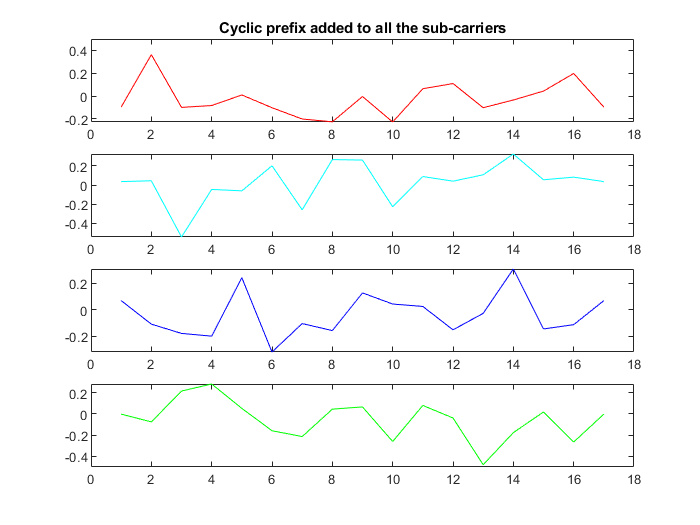

A1=Append_prefix(:,1);
A2=Append_prefix(:,2);
A3=Append_prefix(:,3);
A4=Append_prefix(:,4);
figure(5), subplot(4,1,1),plot(real(A1),'r'),title('Cyclic prefix added to all the sub-carriers')
subplot(4,1,2),plot(real(A2),'c')
subplot(4,1,3),plot(real(A3),'b')
subplot(4,1,4),plot(real(A4),'g')

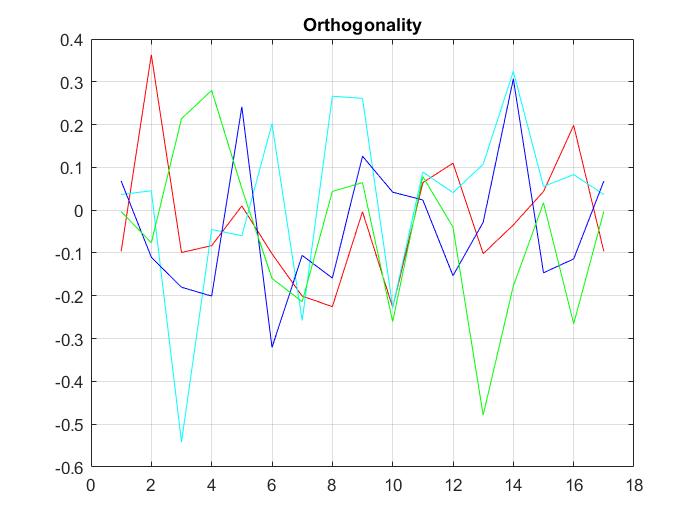


figure(11),plot((real(A1)),'r'),title('Orthogonality'),hold on ,plot((real(A2)),'c'),hold on ,
plot((real(A3)),'b'),hold on ,plot((real(A4)),'g'),hold on ,grid on

%Convert to serial stream for transmission
[rows_Append_prefix cols_Append_prefix]=size(Append_prefix)

rows_Append_prefix = 17

cols_Append_prefix = 4

len_ofdm_data = rows_Append_prefix*cols_Append_prefix

len_ofdm_data = 68

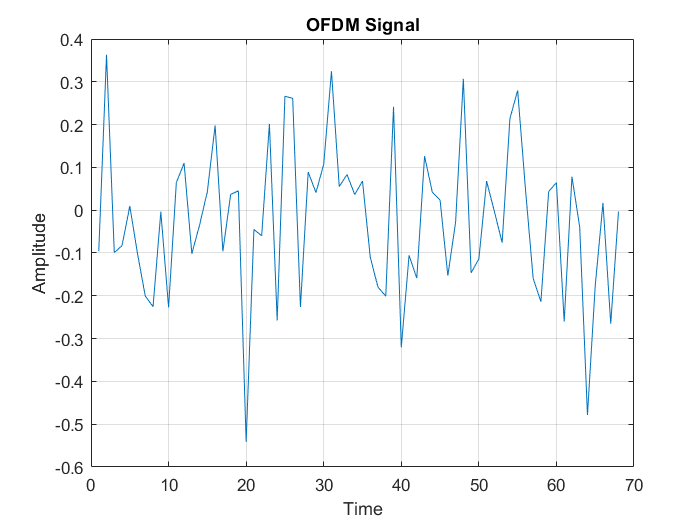

% OFDM signal to be transmitted
ofdm_signal = reshape(Append_prefix, 1, len_ofdm_data);
figure(6),plot(real(ofdm_signal)); xlabel('Time'); ylabel('Amplitude');
title('OFDM Signal');grid on;

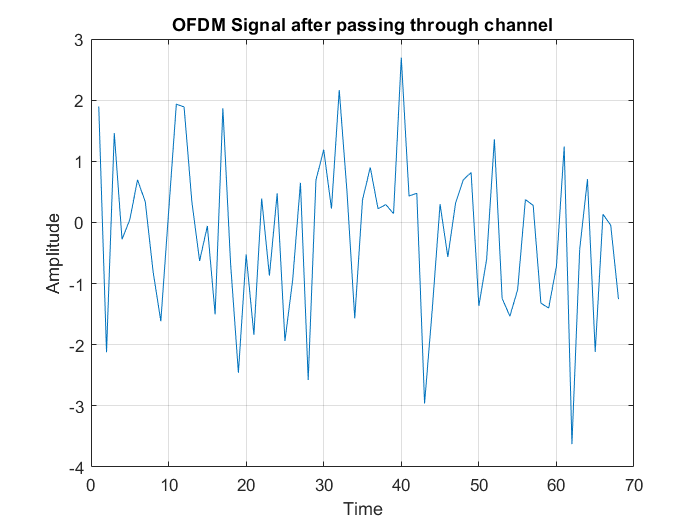

%...............................................................
%.............................................................
channel = randn(1,2) + sqrt(-1)*randn(1,2);
after_channel = filter(channel, 1, ofdm_signal);
awgn_noise = awgn(zeros(1,length(after_channel)),0);
recvd_signal = awgn_noise+after_channel; % With AWGN noise
figure(7),plot(real(recvd_signal)),xlabel('Time'); ylabel('Amplitude');
title('OFDM Signal after passing through channel');grid on;

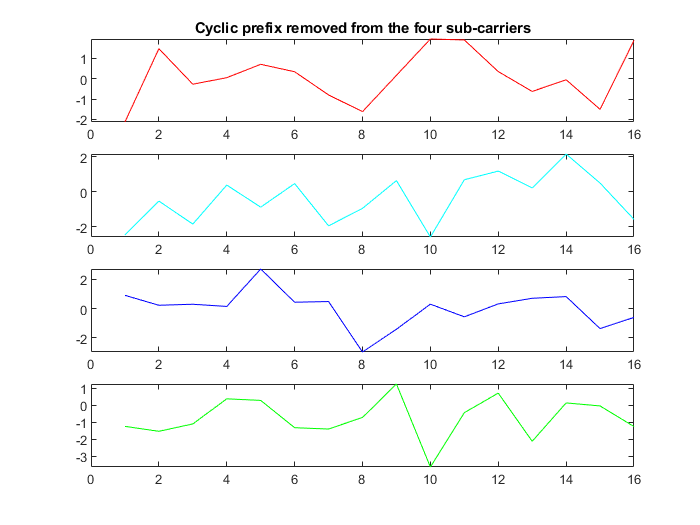

%...........................................................
%%..........................................................
recvd_signal_paralleled = reshape(recvd_signal,rows_Append_prefix, cols_Append_prefix);
%........................................................
%........................................................
% Remove cyclic Prefix
%.......................................................
%......................................................
recvd_signal_paralleled(1:cp_len,:)=[];
R1=recvd_signal_paralleled(:,1);
R2=recvd_signal_paralleled(:,2);
R3=recvd_signal_paralleled(:,3);
R4=recvd_signal_paralleled(:,4);
figure(8),plot((imag(R1)),'r'),subplot(4,1,1),plot(real(R1),'r'),
title('Cyclic prefix removed from the four sub-carriers')
subplot(4,1,2),plot(real(R2),'c')
subplot(4,1,3),plot(real(R3),'b')
subplot(4,1,4),plot(real(R4),'g')

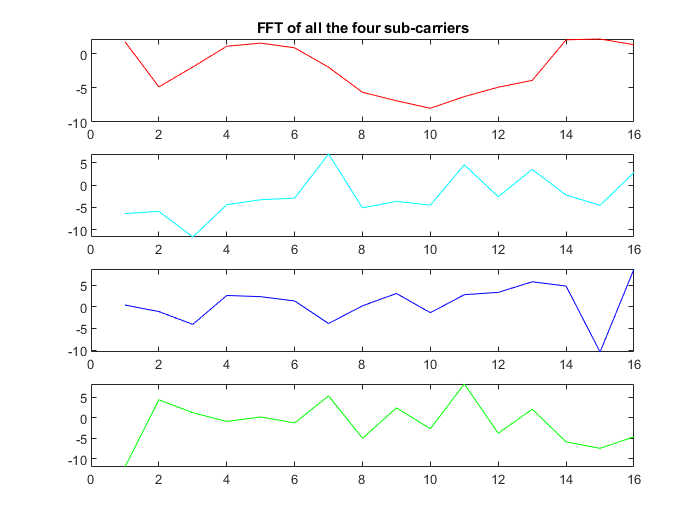

%...................................................
%...................................................
% FFT Of recievied signal
for i=1:number_of_subcarriers
% FFT
fft_data(:,i) = fft(recvd_signal_paralleled(:,i),16);
end
F1=fft_data(:,1);
F2=fft_data(:,2);
F3=fft_data(:,3);
F4=fft_data(:,4);
figure(9), subplot(4,1,1),plot(real(F1),'r'),title('FFT of all the four sub-carriers')
subplot(4,1,2),plot(real(F2),'c')
subplot(4,1,3),plot(real(F3),'b')
subplot(4,1,4),plot(real(F4),'g')

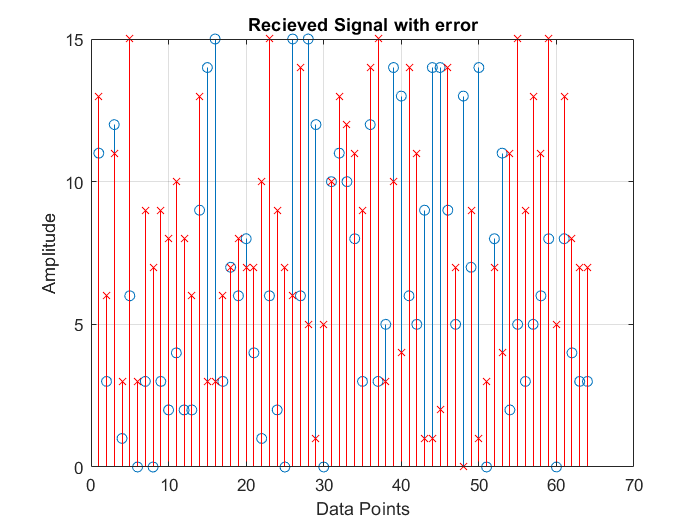

%................................
%..............................
% Signal Reconstructed
%..................................
%..................................
% Conversion to serial and demodulation
recvd_serial_data = reshape(fft_data, 1,(16*4));
qpsk_demodulated_data = pskdemod(recvd_serial_data,block_size);
figure(10)
stem(data)
hold on
stem(qpsk_demodulated_data,'rx');
grid on;xlabel('Data Points');ylabel('Amplitude');
title('Recieved Signal with error')

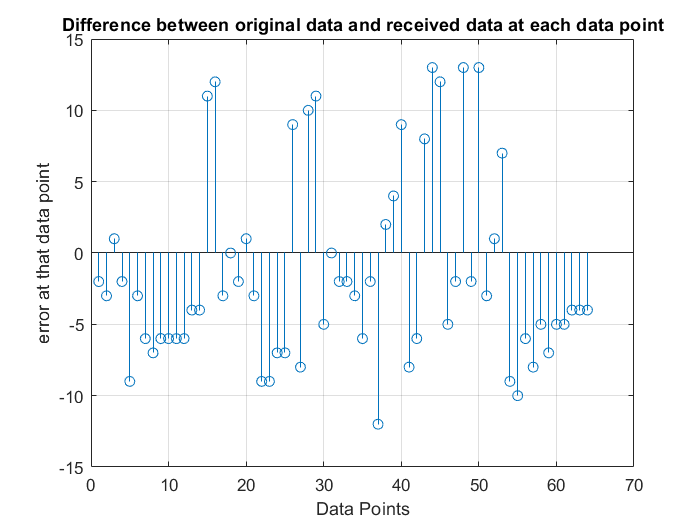

er = zeros(no_of_data_bits, 1);
for i = 1:no_of_data_bits
    er(i)= data(i)- qpsk_demodulated_data(i);
end
figure
stem(er);
title('Difference between original data and received data at each data point');
grid on;xlabel('Data Points');ylabel('error at that data point');